%% ========================================================================
%  SIM_06_SwarmReconfig_WithPerturbation
%  --------------------------------------------------------------
%  - Simulates 5-satellite swarm reconfiguration with small initial
%    velocity perturbations.
%  - Tests robustness of CVX-based fuel-optimal targeting.
%  - Generates trajectory and DeltaV plots.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === ORBIT PARAMETERS ===
mu = 3.986e14;
Re = 6371e3;
alt = 500e3;
a = Re + alt;
n = sqrt(mu / a^3);

T = 2*pi / n;
N_orbits = 1;
dt = 10;
N = round(N_orbits * T / dt);
t_vec = (0:N-1)*dt;

%% === SYSTEM MATRICES ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

B = [zeros(3); eye(3)];

%% === BASE INITIAL CONDITIONS (same as SIM_04) ===
x0_list_clean = {
    [0; 100; 0; 0; 0.1; 0],
    [0; -120; 40; 0; -0.08; 0],
    [30; 80; -50; 0; 0.05; 0],
    [-50; -90; 20; 0; -0.1; 0],
    [60; 0; -30; 0; 0; 0]
};

% Add small velocity perturbations
rng(42); % for reproducibility
perturbation_scale = 0.01; % m/s
x0_list = cellfun(@(x) x + [zeros(3,1); perturbation_scale * randn(3,1)], ...
                  x0_list_clean, 'UniformOutput', false);

%% === TARGET FORMATION (same as SIM_04) ===
target_list = {
    [0; 0; 0; 0; 0; 0],
    [50; 0; 0; 0; 0; 0],
    [-50; 0; 0; 0; 0; 0],
    [0; 50; 0; 0; 0; 0],
    [0; -50; 0; 0; 0; 0]
};

num_sats = 5;
X = cell(num_sats, 1);
U = cell(num_sats, 1);
dV_total = zeros(num_sats, 1);

%% === CVX OPTIMIZATION FOR ALL SATELLITES ===
for i = 1:num_sats
    x0 = x0_list{i};
    x_target = target_list{i};
    
    cvx_begin quiet
        variables x(6, N) u(3, N-1)
        minimize( sum(norms(u, 2, 1)) )
        subject to
            x(:,1) == x0;
            x(:,N) == x_target;
            for k = 1:N-1
                x(:,k+1) == x(:,k) + dt * (A * x(:,k) + B * u(:,k));
            end
    cvx_end
    X{i} = x;
    U{i} = u;
    dV_total(i) = sum(vecnorm(u, 2, 1));
end

%% === TOTAL DELTAV TABLE ===
sat_IDs = (1:num_sats)';
T_dV = table(sat_IDs, dV_total, ...
    'VariableNames', {'Satellite', 'DeltaV'});
disp(' ');

disp('==== Total DeltaV per Satellite (Perturbed) ====');

==== Total DeltaV per Satellite (Perturbed) ====


disp(T_dV);

    Satellite     DeltaV 
    _________    ________

        1         0.22167
        2        0.027595
        3         0.26014
        4         0.07508
        5         0.18041



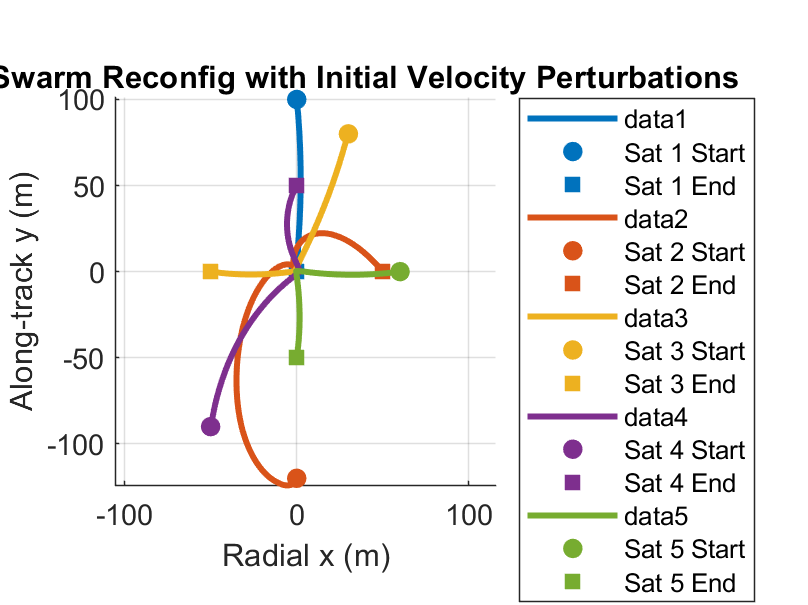


%% === TRAJECTORY PLOT ===
colors = lines(num_sats);
figure; hold on;
for i = 1:num_sats
    x = X{i};
    plot(x(1,:), x(2,:), 'Color', colors(i,:), 'LineWidth', 2);
    plot(x(1,1), x(2,1), 'o', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' Start']);
    plot(x(1,end), x(2,end), 's', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' End']);
end
xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM 06: Swarm Reconfig with Initial Velocity Perturbations');
legend('Location', 'bestoutside');
grid on; axis equal;
saveas(gcf, 'SIM_06_Perturbation_Traj.png');

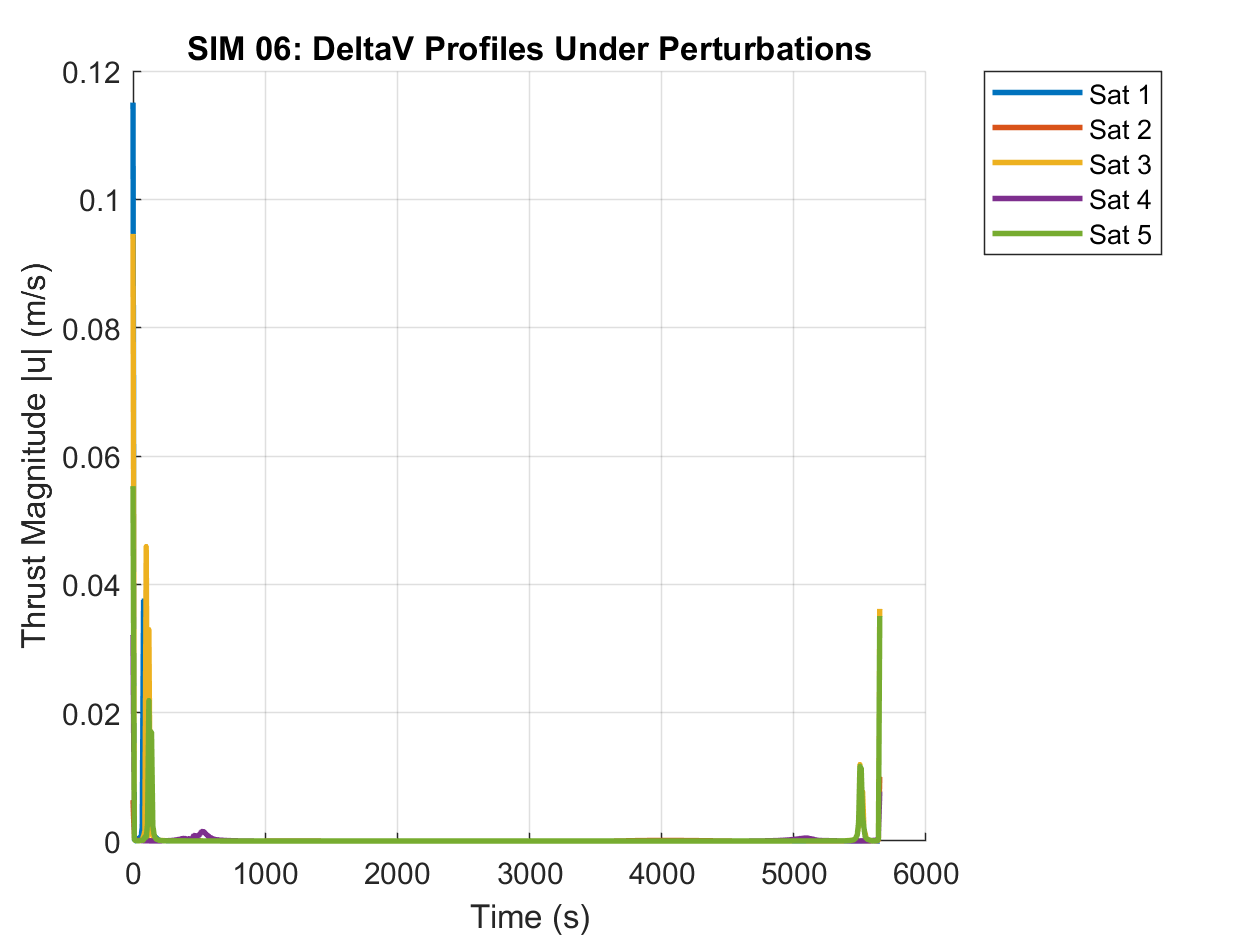


%% === DELTAV PLOT ===
figure; hold on;
for i = 1:num_sats
    u = U{i};
    dV = vecnorm(u, 2, 1);
    plot(t_vec(1:end-1), dV, 'LineWidth', 1.8, 'Color', colors(i,:), ...
        'DisplayName', ['Sat ' num2str(i)]);
end
xlabel('Time (s)');
ylabel('Thrust Magnitude |u| (m/s)');
title('SIM 06: DeltaV Profiles Under Perturbations');
legend('Location', 'bestoutside');
grid on;
saveas(gcf, 'SIM_06_Perturbation_DeltaV.png');


%% === END ===
disp('Simulation completed: SIM_06_SwarmReconfig_WithPerturbation');

Simulation completed: SIM_06_SwarmReconfig_WithPerturbation
